# 4.9 Discrete controller and observer

% select the sampling time
fSamplingPeriod = 0.005;

load poles.mat
load Linear_Param.mat
poles

poles =   -7.8273e+02 + 0.0000e+00i
  -3.9582e+00 + 1.9885e+00i
  -3.9582e+00 - 1.9885e+00i
  -3.3472e-02 + 0.0000e+00i


A;
B = B(:,1);
C = [1 0 0 0;
    0 0 1 0];
D = 0;
contStateSpace = ss(A,B,C,D)

contStateSpace =
 
  A = 
           x1      x2      x3      x4
   x1       0       1       0       0
   x2       0    -435  -6.099   9.136
   x3       0       0       0       1
   x4       0    1903   62.02  -39.97
 
  B = 
           u1
   x1       0
   x2   20.58
   x3       0
   x4  -90.03
 
  C = 
       x1  x2  x3  x4
   y1   1   0   0   0
   y2   0   0   1   0
 
  D = 
       u1
   y1   0
   y2   0
 
Continuous-time state-space model.



discreteStateSpace = c2d(contStateSpace,fSamplingPeriod);
Ad = discreteStateSpace.A

Ad =    1.0000e+00   2.1694e-03  -3.5615e-05   5.9372e-05
            0   1.6926e-01  -9.5490e-03   1.7410e-02
            0   1.2386e-02   1.0006e+00   4.7409e-03
            0   3.6357e+00   2.1849e-01   9.2425e-01


Bd = discreteStateSpace.B

Bd =    1.3388e-04
   3.9292e-02
  -5.8583e-04
  -1.7196e-01


Cd = discreteStateSpace.C

Cd =      1     0     0     0
     0     0     1     0


D = discreteStateSpace.D

D =      0
     0


discretePoles = exp(poles*fSamplingPeriod)

discretePoles =    1.9967e-02 + 0.0000e+00i
   9.8035e-01 + 9.7474e-03i
   9.8035e-01 - 9.7474e-03i
   9.9983e-01 + 0.0000e+00i



%Plotting discrete poles
scatter(real(discretePoles),imag(discretePoles))
hold on
r = 1

r =      1


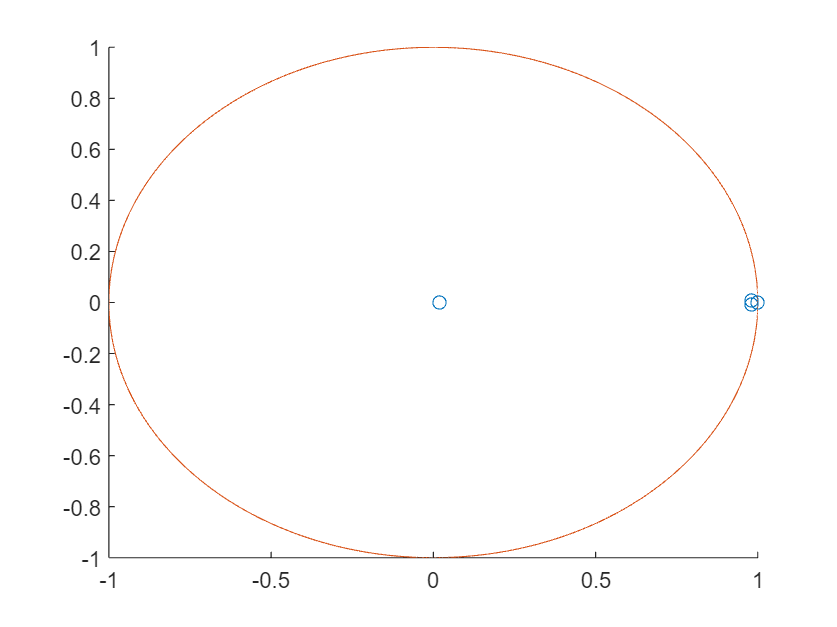

ang=0:0.01:2*pi; 
xp=r*cos(ang);
yp=r*sin(ang);
plot(xp,yp);
hold off

Controller

%State-feedback gain
Kd = place(Ad,Bd,discretePoles)

Kd =   -4.5450e-01  -3.4907e+01  -4.6100e+01  -8.4800e+00


eig(Ad-Bd*Kd)

ans =    1.9967e-02 + 0.0000e+00i
   9.9983e-01 + 0.0000e+00i
   9.8035e-01 + 9.7474e-03i
   9.8035e-01 - 9.7474e-03i


Full-state observer

factor = 4;
speed = max(abs(poles(2:4)));
contObserverPoles(1) = poles(1);
contObserverPoles(2) = -6*factor*speed; % Place pole to not disturb dominant poles

omegan = factor*speed;
zeta = 0.8;
contObserverPoles(3:4) =    [omegan*(-zeta+1i*sqrt(1-zeta^2));
                omegan*(-zeta-1i*sqrt(1-zeta^2))];
desiredPoles = exp(contObserverPoles*factor*fSamplingPeriod)

desiredPoles =    1.5896e-07 + 0.0000e+00i   1.1929e-01 + 0.0000e+00i   7.3618e-01 + 1.5893e-01i   7.3618e-01 - 1.5893e-01i


Ld = (place(Ad',Cd',desiredPoles))'

Ld =    9.9124e-01   4.2779e-02
  -1.1265e+00  -1.0628e+00
  -2.6236e-01   5.1121e-01
  -6.1250e+01   2.3125e+01


eig(Ad-Ld*Cd)

ans =    7.3618e-01 + 1.5893e-01i
   7.3618e-01 - 1.5893e-01i
   1.5896e-07 + 0.0000e+00i
   1.1929e-01 + 0.0000e+00i


Reduced order observer

T = inv([C;0 1 0 0; 0 0 0 1])

T =      1     0     0     0
     0     0     0     1
     0     1     0     0
     0     0     1     0


An = inv(T)*Ad*T ;  %New A-matrix
Bn = inv(T)*Bd;     %New B-matrix
Cbacc = Cd(1,:)*T;  %Accurate
Cbnacc = Cd(2,:)*T; %Not accurate

Ayy = An(1,1); %Zero
Ayx = An(1,2:4);  %Noisy/unobserved states
Axy = An(2:4,1); % Zero
Axx = An(2:4,2:4); %Noisy/unobserved states

By = Bn(1);
Bx = Bn(2:4);

Cy = Cbnacc(1);
Cx = Cbnacc(2:4);

AA = Axx;
CC = [Ayx
      Cx];
Lpartial = ( place( AA', CC', desiredPoles(2:4) ) )';
Lacc = Lpartial(:,1);
Lnacc = Lpartial(:,2);

poles(2:4);
observerPoles = eig(AA-Lpartial*CC)

observerPoles =    1.1929e-01 + 0.0000e+00i
   7.3618e-01 + 1.5893e-01i
   7.3618e-01 - 1.5893e-01i



M1d = Axx-Lacc*Ayx-Lnacc*Cx

M1d =    1.2737e-01   6.1750e-03   6.4785e-02
  -1.1255e-01   7.9950e-01  -9.2243e-01
   6.8034e-02   3.0971e-02   6.6478e-01


M2d = Bx-Lacc*By

M2d =    2.6479e-03
  -4.5325e-01
   6.9872e-02


M3d = Axy-Lacc*Ayy-Lnacc*Cy

M3d =    2.4154e+01
  -2.1011e+03
   2.2842e+02


M4d = Lnacc

M4d =    8.7236e-01
   4.0586e-01
  -8.5718e-02


M5d = Lacc

M5d =   -2.4154e+01
   2.1011e+03
  -2.2842e+02


M6d = T(:,1)

M6d =      1
     0
     0
     0


M7d = T(:,2:4)

M7d =      0     0     0
     0     0     1
     1     0     0
     0     1     0
